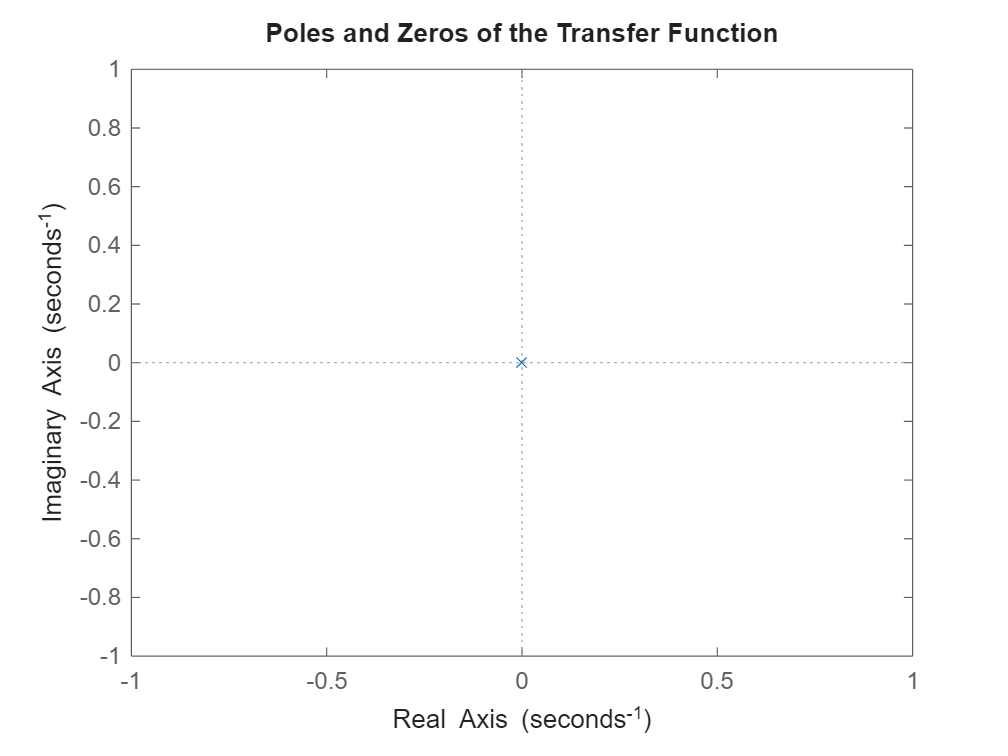

% Parameters
m = 0.01;  %  (kg)
R = 0.015; %  (m)
d = 0.03;  %(m)
L = 0.34;  %  (m)
g = 9.81;  %  (m/s^2)

% Transfer function P(s)
numerator = 5 * g * d / (7 * L); 
denominator = [1 0 0]; 
P = tf(numerator, denominator);

% Plot poles and zeros
figure;
pzmap(P);
title('Poles and Zeros of the Transfer Function');

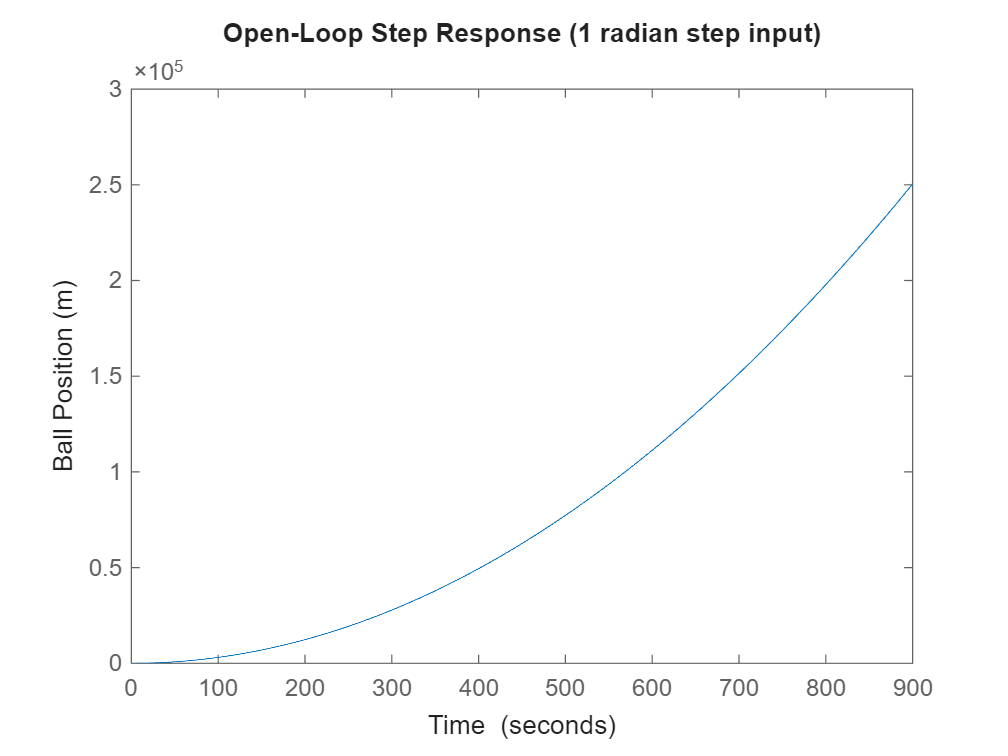


% Open-loop step response
figure;
step(P);
title('Open-Loop Step Response (1 radian step input)');
xlabel('Time ');
ylabel('Ball Position (m)');